# Homework 6

Math 3607, Autumn 2021

Marco LoPiccolo

## Problem 1.

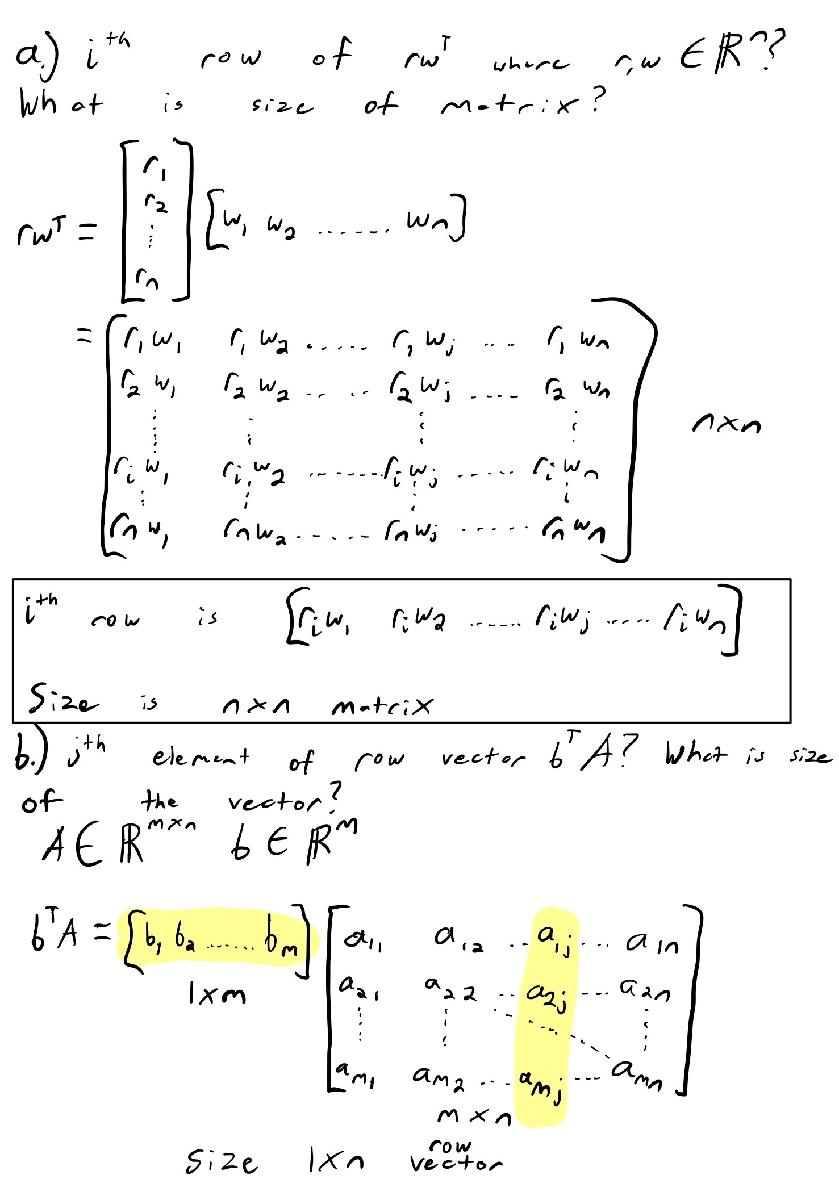

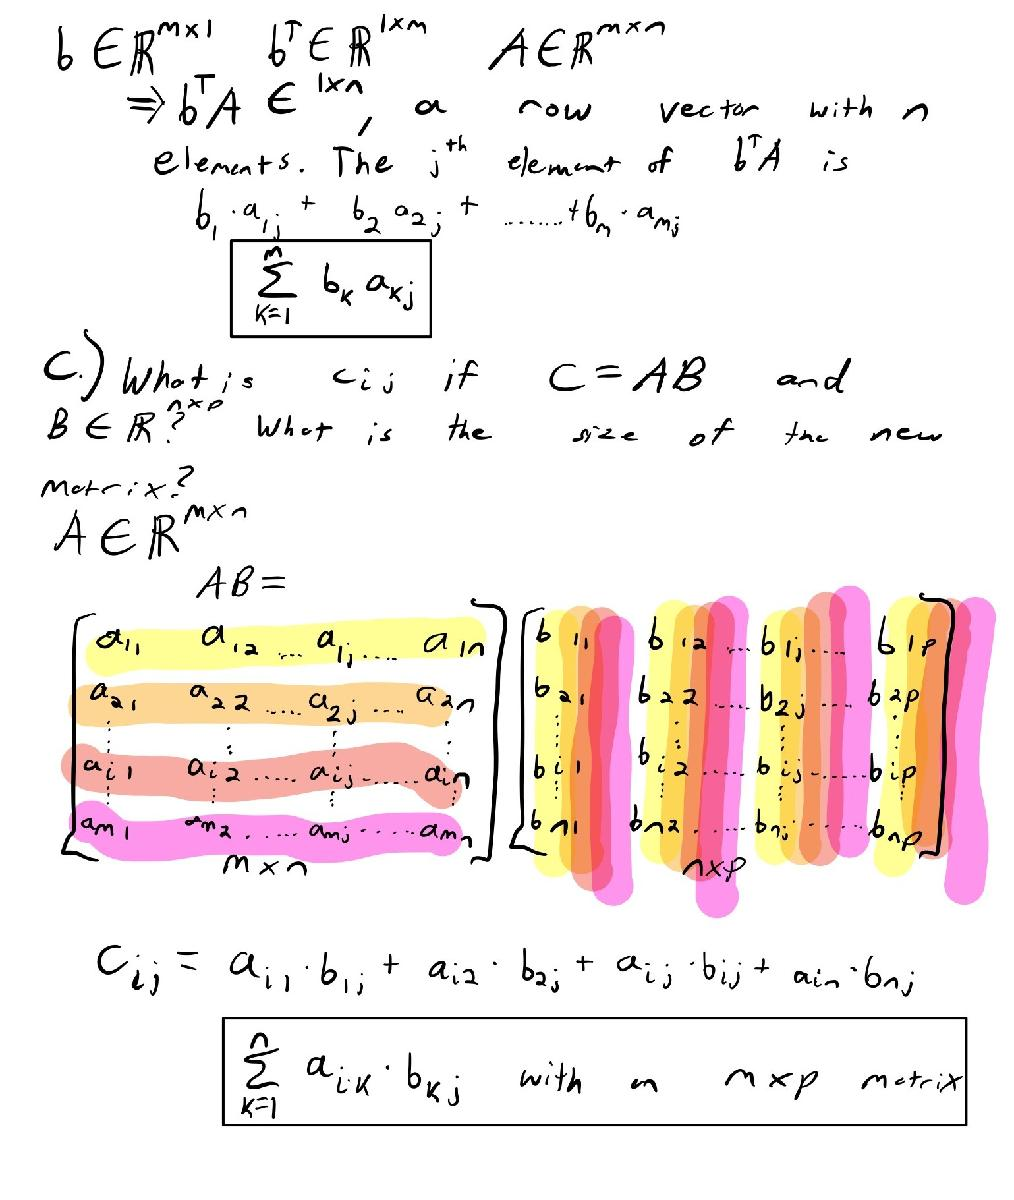

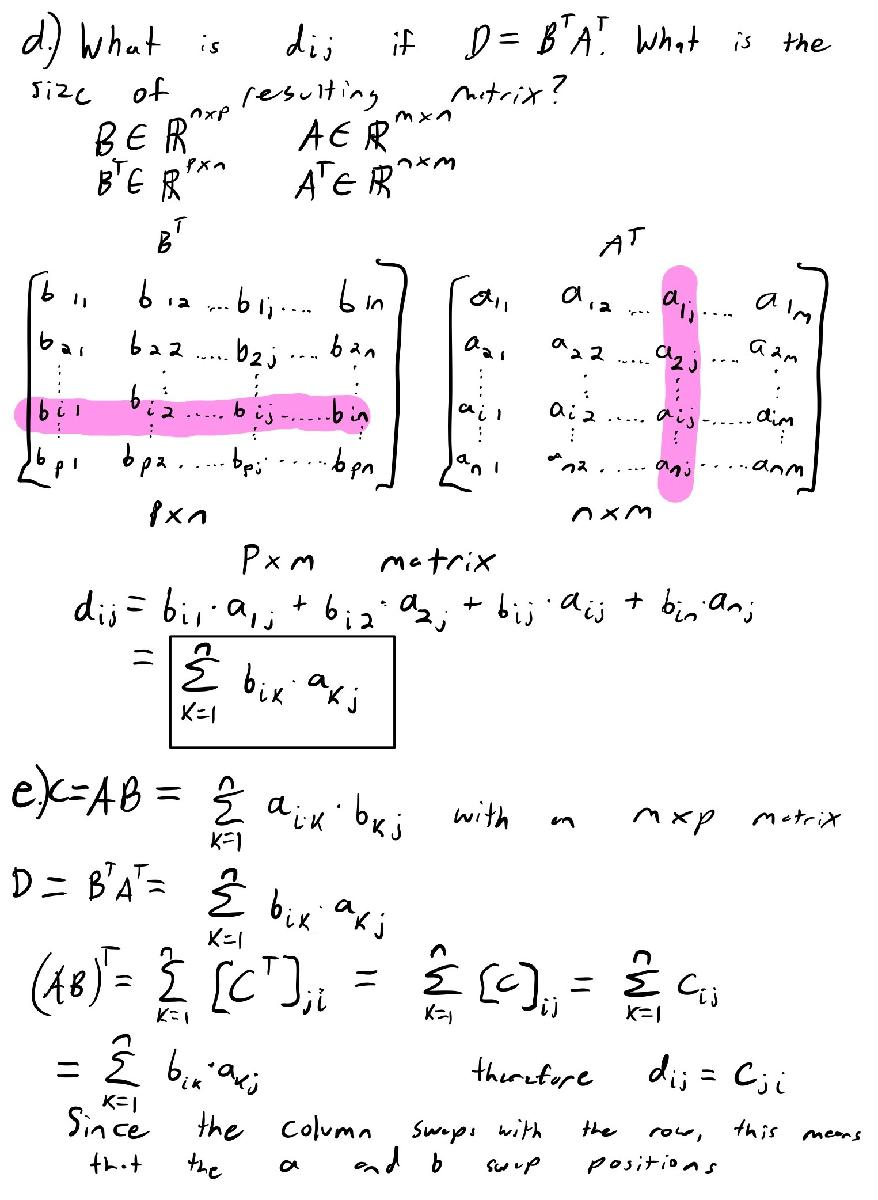

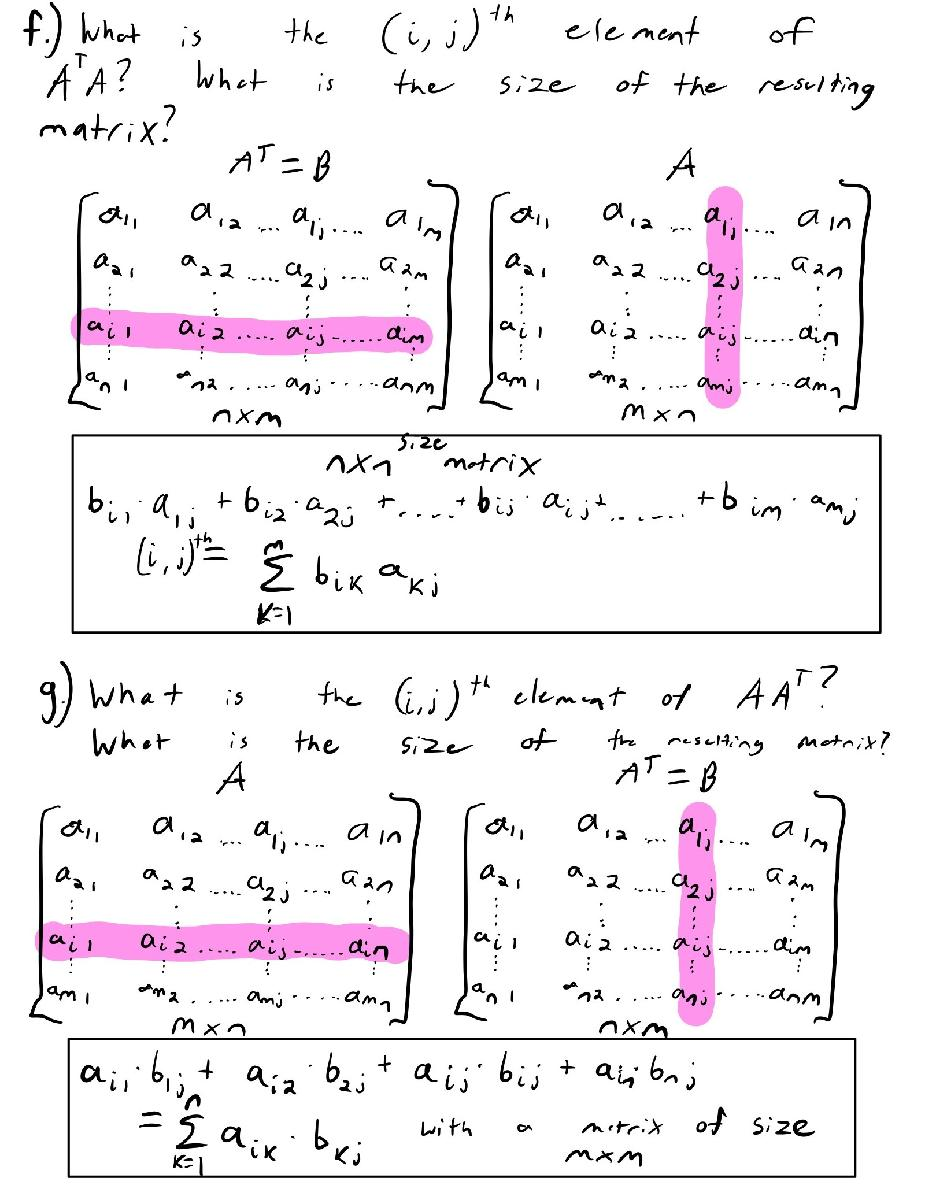

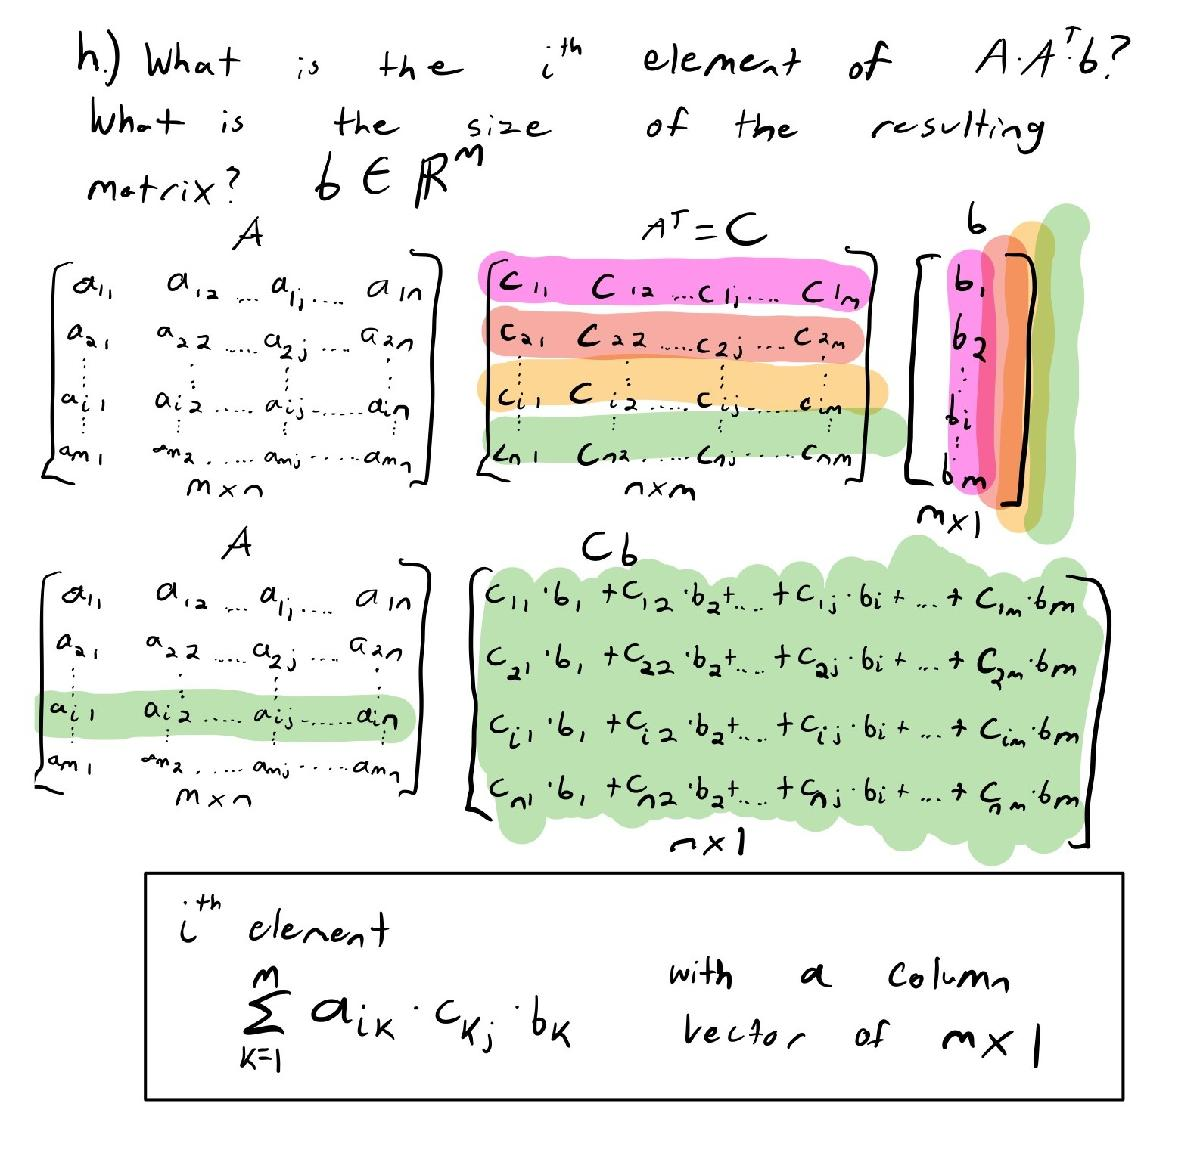

## Problem 2.

%A = [1 1 1 1; 1 0 0 1; 4 2 -2 1]';
m = 500;
n = 20;
A = randn(m,n);
[Q, R] = qr(A, 0);
[Q, R] = GramSchmidt(A);
%Check Q^T*Q - I = 0
%check A - Q*R = 0 
norm(Q'*Q - eye(n,n))

ans = 4.6463e-16

norm(A - Q*R)

ans = 5.1706e-15

## Problem 3. 

#### Part a.)

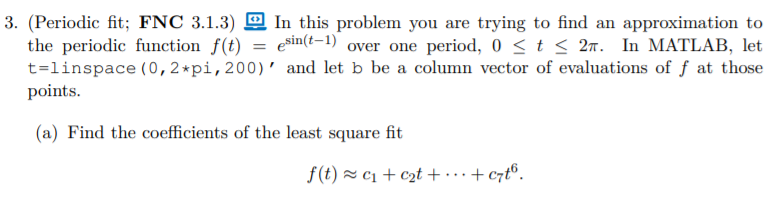

t=linspace(0,2*pi,20)';
y = exp(sin(t - 1));
n = 7;
V = t .^ (0:n-1);
c = V \ y;

#### Part b.)

X = [ones(size(t)) cos(t) sin(t) cos(2*t) sin(2*t)];
% d2 = cos(t);
% d3 = sin(t);
% d4 = cos(2.*t);
% d5 = sin(2.*t);
% X = [d1 d2 d3 d4 d5]
d = X \ y;

#### Part c.)

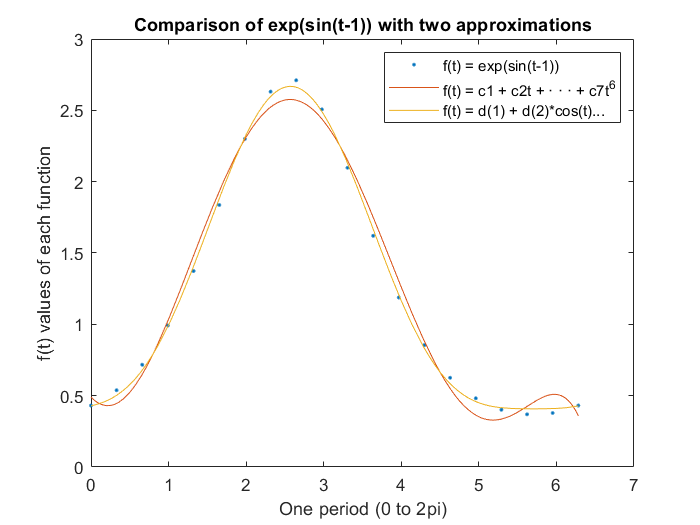

clf
plot(t, y, '.'), hold on
p = @(t) polyval(flip(c), t);
f = @(t) d(1) + d(2)*cos(t) + d(3)*sin(t) + d(4)*cos(2*t) + d(5)*sin(2*t);
fplot(p, [0 2*pi])
fplot(f, [0 2*pi])
xlabel('One period (0 to 2pi)')
ylabel('f(t) values of each function')
title('Comparison of exp(sin(t-1)) with two approximations')
legend('f(t) = exp(sin(t-1))', 'f(t) = c1 + c2t + · · · + c7t^6', ...
    'f(t) = d(1) + d(2)*cos(t)...')

## Problem 4. 

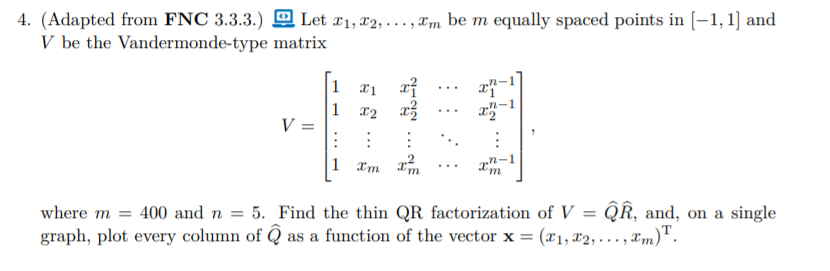

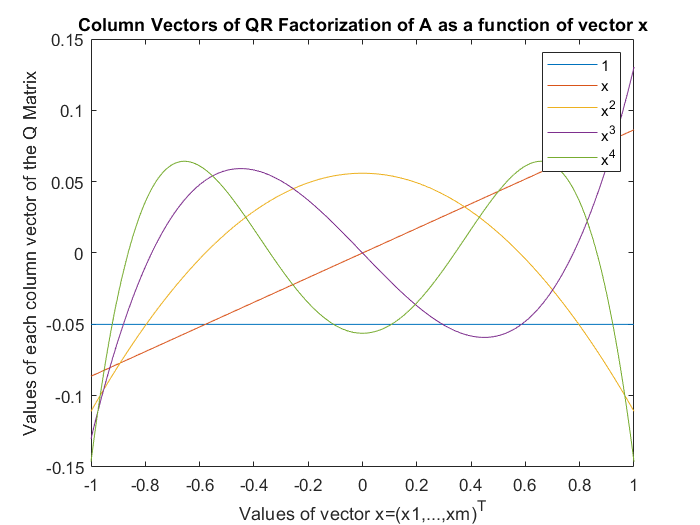

xpre = linspace(-1,1,400)';
n = 5;
V = [ones(400,1) xpre .^ (1:n-1)];
[Q, R] = qr(V, 0);
% one = Q(:,1)
% x1 = Q(:,2)
% x2 = Q(:,3)
% x3 = Q(:,4)
% x4 = Q(:,5)
clf
%plot(xpre, one, xpre, x1, xpre, x2, xpre, x3, xpre, x4)
plot(xpre, Q)
xlabel('Values of vector x=(x1,...,xm)^T')
ylabel('Values of each column vector of the Q Matrix')
title('Column Vectors of QR Factorization of A as a function of vector x')
legend('1','x','x^2','x^3','x^4')

## Problem 5. 

#### Part a.)

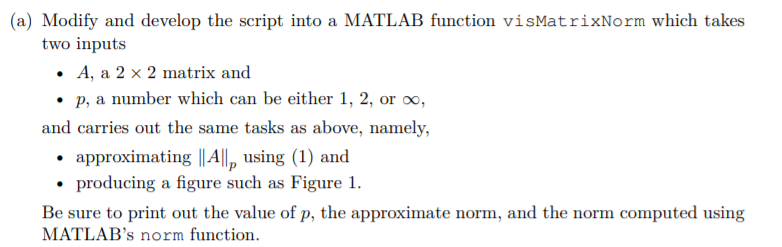

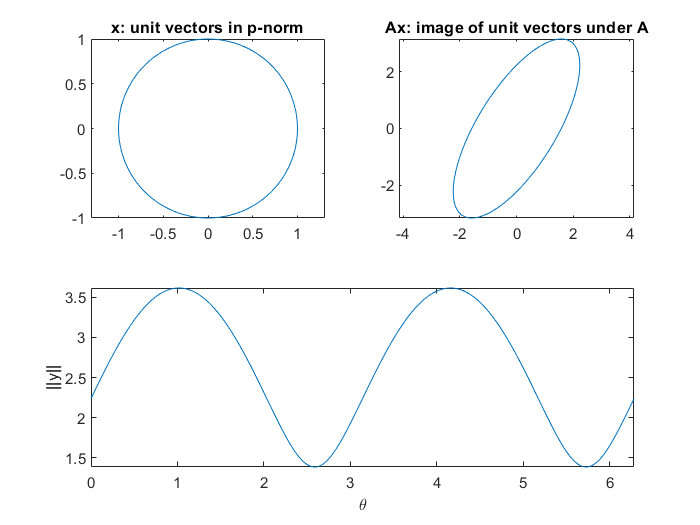

 p = 2.0000000000000000
 approx. norm: 3.6179964204609893
 actual norm: 3.6180339887498953


A = [2 1;
     1 3];
p = 2;
[~] = visMatrixNorm(A, p)

#### Part b.)

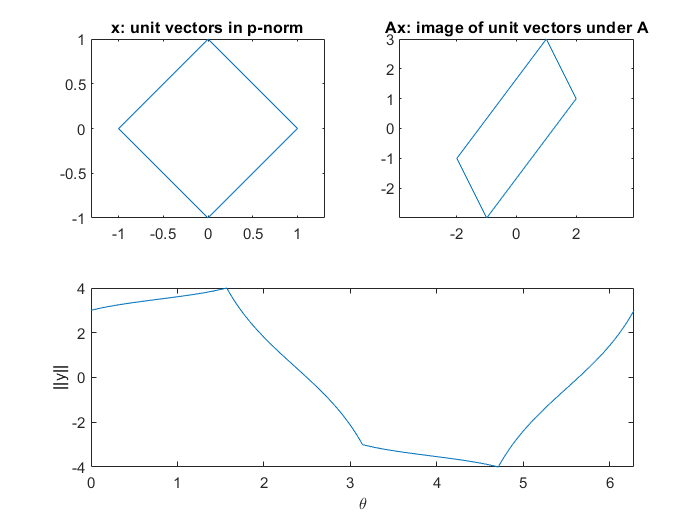

 p = 1.0000000000000000
 approx. norm: 4.0000000000000000
 actual norm: 4.0000000000000000


p = 1;
[~] = visMatrixNorm(A, p)

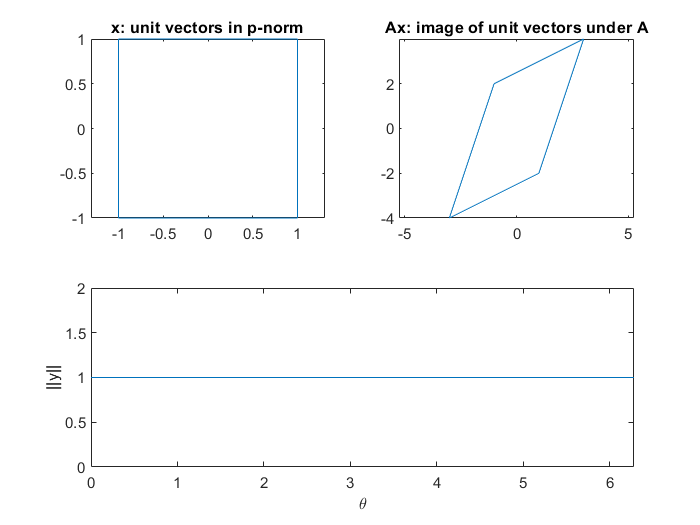

 p =                Inf
 approx. norm: 1.0000000000000000
 actual norm: 4.0000000000000000


p = inf;
[~] = visMatrixNorm(A, p)

## Function Gram-Schmidt

function [Q,R] = GramSchmidt(A)
% GramSchmidt computes both Q and R for the procedure of thin QR
% factorization
% input:
% A 
% output:
% The orthonormal matrix Q and the upper triangular matrix R
[m,n] = size(A);
Q = A;
R = zeros(n);
for j=1:n
    for i=1:j-1
       R(i,j) = (Q(:,i)' * A(:,j));
       Q(:,j) = Q(:,j) - R(i,j)*Q(:,i);
    end
    R(j,j) = norm(Q(:,j), 2);
    Q(:,j) = Q(:,j) / R(j,j);
end
end


## Function visMatrixNorm

function [Y] = visMatrixNorm(A, p)
% visMatrixNorm computes and prints out the approximate norm versus the actual norm
% given an input of matrix A which is a square matrix and p is the norm value
% The function outputs Y which is the image of the unit vectors under A and also prints out 
% the approximate norm versus the actual norm 

theta = linspace(0, 2*pi, 361);
X = [cos(theta); sin(theta)];        
for j = 1:361
    X(:,j) = X(:,j)/norm(X(:,j),p);  % x: unit vectors in 2-norm
    Y = A*X;                         % y: images of x under A
    norm_Y = (sum(Y.^p, 1)).^(1/p);
end

% visualization
clf
subplot(2,2,1)
plot(X(1,:), X(2,:)), axis equal
title('x: unit vectors in p-norm')
subplot(2,2,2)

plot(Y(1,:), Y(2,:)), axis equal
title('Ax: image of unit vectors under A')
subplot(2,1,2)

plot(theta, norm_Y), axis tight
xlabel('\theta') 
ylabel('||y||')

% matrix norm approximation (and comparison)
fprintf(' p = %18.16f\n', p)
fprintf(' approx. norm: %18.16f\n', max(norm_Y))
fprintf(' actual norm: %18.16f\n', norm(A, p))

end